m=4;
k=1:m;
x=sort(cos((2*k-1)*pi/(2*m)));
f = @(x) x.^2.*sin(2*pi*x);
fd = @(x) 2*x.*sin(2*pi*x) + 2*x.^2*pi.*cos(2*pi*x);
fdd = @(x) 2*sin(2*pi*x) - 4*x.^2*pi^2.*sin(2*pi*x) + 8*x*pi.*cos(2*pi*x);
y=f(x);
fd1=fd([-1,1]);
fd2=fdd([-1,1]);
cc1=CubicSplinec(x,y,0,fd1)

cc1 =    22.5301  -25.4804    6.2832    0.3928
   -5.9989    6.8871   -1.4998   -0.0984
   22.5301  -11.0992   -1.4998    0.0984


cc2=CubicSplinec(x,y,1,fd2)

cc2 =    11.6379  -12.5664    2.4844    0.3928
   -3.9213    4.5019   -0.8913   -0.0984
   11.6379   -6.3288   -0.8913    0.0984


cc3=CubicSplinec(x,y,2)

cc3 =     1.0390    0.0000   -1.2121    0.3928
   -1.8997    2.1809   -0.2992   -0.0984
    1.0390   -1.6868   -0.2992    0.0984


cc4=CubicSplinec(x,y,3)

cc4 =    -0.5137    1.8409   -1.7536    0.3928
   -1.6035    1.8409   -0.2124   -0.0984
   -0.5137   -1.0068   -0.2124    0.0984


2 Evaluati spline-ul pe o multime de puncte

t=linspace(-1,1,200);

z1=evalsplinec(x,cc1,t)

z1 =    -0.2430
   -0.1400
   -0.0431
    0.0480
    0.1332
    0.2129
    0.2870
    0.3558
    0.4193
    0.4777


z2=evalsplinec(x,cc2,t)

z2 =     0.1258
    0.1705
    0.2122
    0.2510
    0.2869
    0.3200
    0.3504
    0.3781
    0.4033
    0.4259


z3=evalsplinec(x,cc3,t)

z3 =     0.4847
    0.4726
    0.4606
    0.4485
    0.4363
    0.4242
    0.4120
    0.3998
    0.3877
    0.3755


z4=evalsplinec(x,cc4,t)

z4 =     0.5372
    0.5169
    0.4970
    0.4774
    0.4582
    0.4395
    0.4211
    0.4030
    0.3854
    0.3681


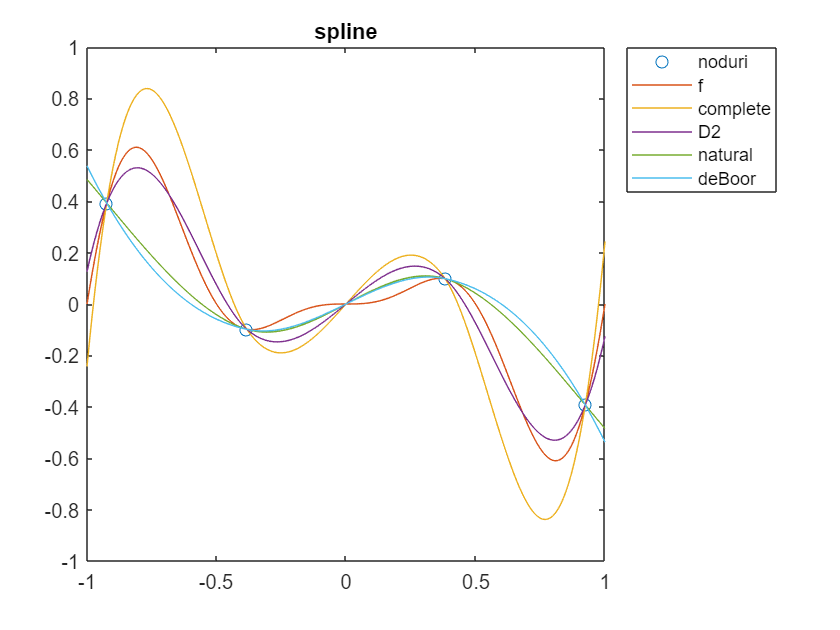

ft=f(t');

figure(1)
plot(x,y,'o',t,f(t),t,[z1,z2,z3,z4])
legend('noduri','f','complete','D2','natural','deBoor','Location','bestoutside');
title('spline')